#  Running MONAI model inference in MATLAB

This script walks through the process of importing an image segmentation model trained using MONAI into MATLAB. 

This has been tested on Mac OS Sonoma 14.5 with MATLAB R2024b running the Intel build. 

### Heart Segmentation Task: label the pixels in the left atrium:

Read image data from NIfTI files in the Medical Segmentation Decathlon (Task 02):

img = niftiread("data/la_030.nii.gz");
gt_label = niftiread("data/label_la_030.nii.gz");

% Visualize the volume and ground truth labels:
%volumeSegmenter

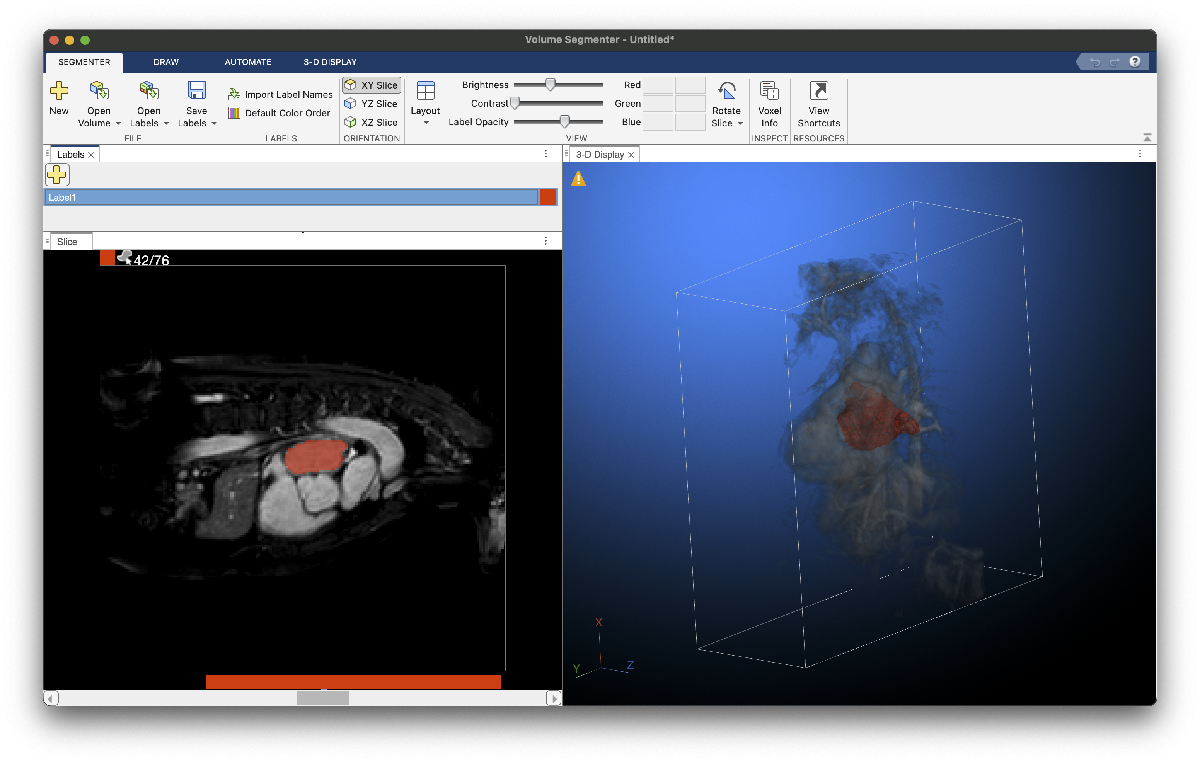

### Making available the custom written python module into MATLAB:

Importing a custom module to interact between MATLAB and functions written to load the U-Net model, and run inference.

To get things running, we will first setup the dependent conda environment.

terminate(pyenv)
pyversion('/Users/amithkamath/opt/anaconda3/envs/matlab-monai/bin/python')

Now, import the python bridge file we have created to expose python functions to the MATLAB environment:

py.importlib.import_module('matlab_monai_bridge')

ans =   Python module with properties:

                   save_data: [1×1 py.function]
                create_model: [1×1 py.function]
                        UNet: [1×1 py.type]
                 Activations: [1×1 py.abc.ABCMeta]
                  test_model: [1×1 py.function]
                   LoadImage: [1×1 py.abc.ABCMeta]
              ScaleIntensity: [1×1 py.abc.ABCMeta]
               NibabelWriter: [1×1 py.type]
                       torch: [1×1 py.module]
                          re: [1×1 py.module]
                        Norm: [1×1 py.monai.networks.layers.factories.LayerFactory]
                          os: [1×1 py.module]
               get_transform: [1×1 py.function]
                     Compose: [1×1 py.abc.ABCMeta]
                  AsDiscrete: [1×1 py.abc.ABCMeta]
                     Spacing: [1×1 py.abc.ABCMeta]
                   inference: [1×1 py.function]
                  save_model: [1×1 

### Import model into MATLAB:

Creating the MONAI version of the U-Net in MATLAB using the create_model function:

monaiUNet = py.matlab_monai_bridge.create_model("models/trained_msd_heart_model.ckpt")

monaiUNet =   Python UNet with properties:

      out_channels: [1×1 py.int]
     num_res_units: [1×1 py.int]
          channels: [1×6 py.tuple]
          training: 1
               act: [1×4 py.str]
           dropout: 0
      adn_ordering: [1×3 py.str]
       kernel_size: [1×1 py.int]
       in_channels: [1×1 py.int]
              norm: [1×5 py.str]
    up_kernel_size: [1×1 py.int]
           strides: [1×5 py.tuple]
              bias: 0
        dimensions: [1×1 py.int]

    UNet(
      (model): Sequential(
        (0): Convolution(
          (conv): Conv3d(1, 16, kernel_size=(3, 3, 3), stride=(2, 2, 2), padding=(1, 1, 1), bias=False)
          (adn): ADN(
            (N): BatchNorm3d(16, eps=1e-05, momentum=0.1, affine=True, track_running_stats=True)
            (D): Dropout(p=0.0, inplace=False)
            (A): ReLU()
          )
        )
        (1): SkipConnection(
          (submodule):

Running inference using the python function from the custom imported module:

seg = py.matlab_monai_bridge.inference(monaiUNet, "data/la_030.nii.gz");

Displaying the segmentation results along with the image:

seg_array = squeeze(logical(py.numpy.array(seg)));
size(seg_array)

ans =      2   200   200    76


Evaluate performance of model using Dice score coefficient:

tformed_gt = niftiread("data/tformed_label_la_030.nii.gz");
dice(squeeze(seg_array(2, :, :, :)), logical(tformed_gt))

ans = 0.8601

### Load model directly with pytorch support package:

This model can also be displayed in the `deep network designer `app. 

See `matlab_monai_bridge.py` for how to save the checkpointed model as a `.pt` file.

model = importNetworkFromPyTorch("models/msd_heart_model.pt");

% Display model with Deep Network Designer:
%deepNetworkDesigner(model)

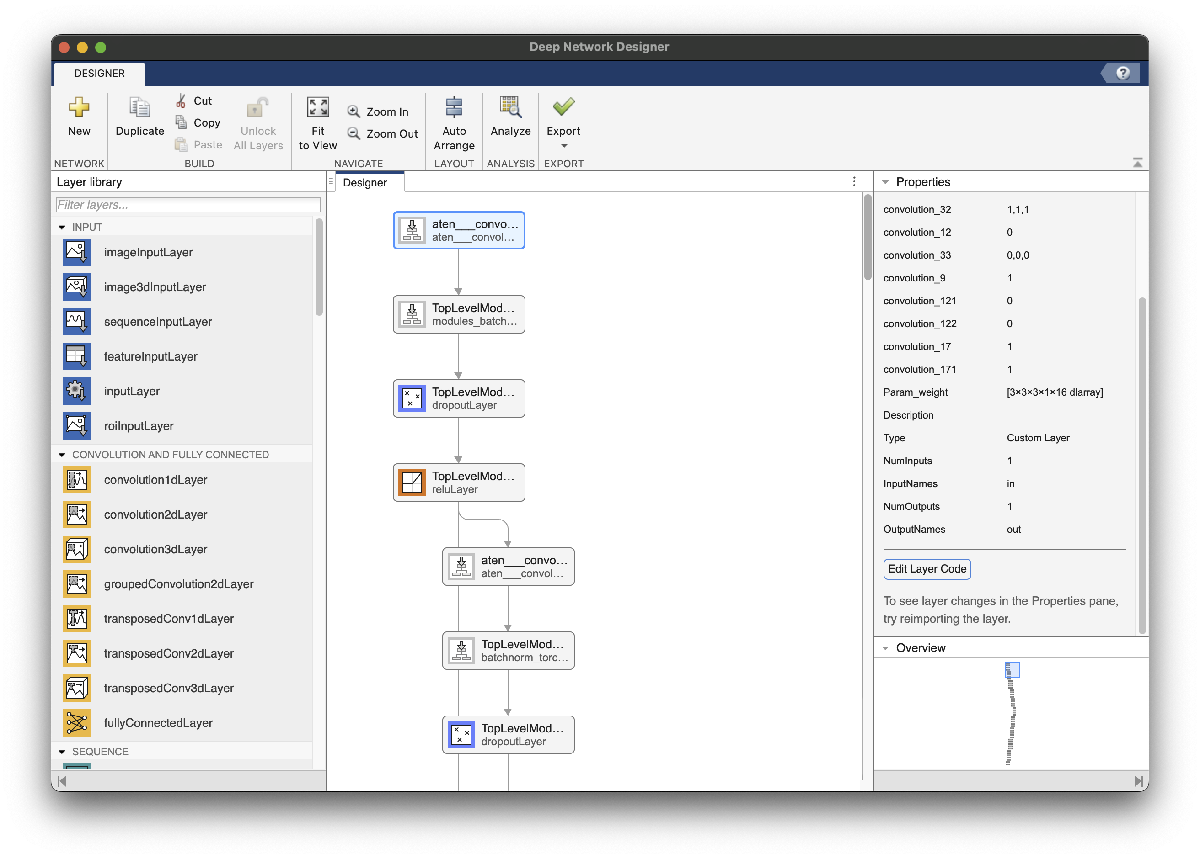

*Copyright 2024 The MathWorks Inc.*